Generate three sinusoidal signals x1(k), x2(k) and x3(k) with a fundamental frequency of 50, 100Hz and 150Hz, respectively, amplitude A = 1, sampling frequency equal to 1kHz and duration equal to 1 s.

Generate x4(k)=x1(k)+x2(k)+x3(k). 	

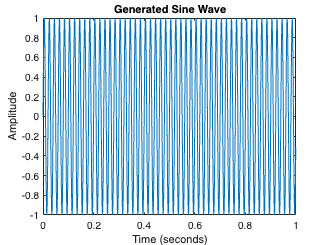

f1 = 50; %Hz
f2 =  100; %Hz
f3 =  150; %Hz
A = 1; % amplitude
f_s = 1000;
t = [0:1/1000:1];
d = 1 - 0; % duration


% function [x]=generate_sine(frequency,A,fs,duration)
x1 = generate_sine(f1, A, f_s, d);

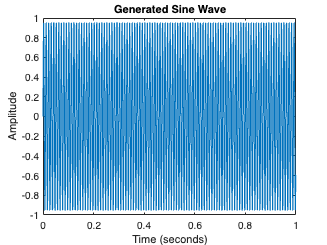

x2 = generate_sine(f2, A, f_s, d);

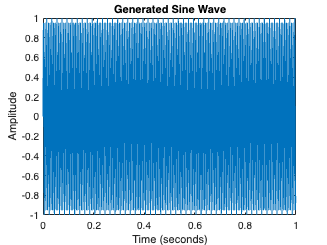

x3 = generate_sine(f3, A, f_s, d);


x4 = x1 + x2 + x3;


# **Burg **

Matlab has two precompiled function for implementing the PSD parametric estimation through the Burg method: *arburg.m *and *pburg.m*. Check the help of the functions to study the inputs and the outputs. 			

**Apply the functions on signal x4(k) and analyze the effect of the order on the PSD estimation. **


% Parameters for Burg method
threshold_burg = 0.00001; % Variation threshold of eb
max_order_burg = 100; % Max order to consider
eb_values = zeros(1, max_order_burg); % Store variance values

% Initialization of previous eb to compare
[~, prev_eb] = arburg(x4, 1); % Only eb is needed from the first order

% Burg method to find optimal order
for order_burg = 2:max_order_burg
    % Calculate the coefficient and the variance of AR
    [~, eb] = arburg(x4, order_burg);
    
    eb_values(order_burg) = eb; % Store error variance for current order

    % Monitor the variance of eb
    if abs(prev_eb - eb) < threshold_burg
        fprintf('The optimal order is %d with eb = %.6f\n', order_burg, eb);
        break;
    end

    % Update the previous eb
    prev_eb = eb;
    
    % If it gets up to the max order without satisfying the conditions
    if order_burg == max_order_burg
        fprintf('Reached the maximum order (%d) with eb = %.6f\n', max_order_burg, eb);
    end
end

The optimal order is 7 with eb = 0.000000


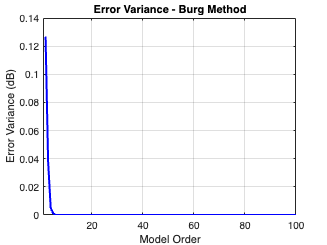


% Plotting error variance for Burg method
figure;
plot(2:max_order_burg, eb_values(2:end), 'b-', 'LineWidth', 2); % eb_values for orders 2 to max
title('Error Variance - Burg Method');
xlabel('Model Order');
ylabel('Error Variance (dB)');
xlim([1 max_order_burg]);
grid on;

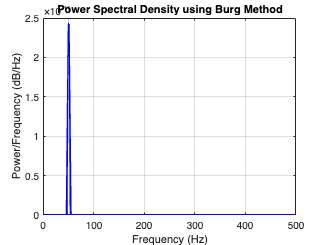


% PSD estimation using optimal Burg order
optimal_order_burg = find(eb_values == min(eb_values), 1, 'last'); % Ensure it captures the last minimal variance
[pxx_burg, f] = pburg(x4, optimal_order_burg, [], f_s);

% Plot the Power Spectral Density
figure;
plot(f, pxx_burg, 'b', 'LineWidth', 2); % Convert power to dB/Hz
title('Power Spectral Density using Burg Method');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

**Error Variance Plot**:

- The error variance decreases rapidly and stabilizes around model order 7.

- Indicates that increasing the model order beyond 7 does not significantly reduce the error variance.

- Suggests that the Burg method captures the signal characteristics effectively at a relatively low order.

**Power Spectral Density (PSD) Plot**:

- PSD shows a distinct peak at 50 Hz.

- Peaks correspond to the fundamental frequencies of the sinusoidal components in the signal.

- Sharp and high peaks demonstrate the accuracy of the Burg method in estimating the PSD for signals with clear frequency components.

**Conclusion**:

- The Burg method effectively identifies the optimal model order and accurately estimates the PSD of the combined sinusoidal signal.

- The error variance plot and PSD plot together confirm the method's capability to capture significant spectral components and signal dynamics accurately.